time3 = DYOErunsaani31714230.AnalogChannels; 
duration = max(time3) - min(time3)

duration = 4.9900

signal3 = DYOErunsaani31714230.VarName5; 
k = [time3,signal3]; 

% determine sampling frequency
Fs = 1 / mean(diff(time3));  % Sampling frequency in Hz



% analyze frequency components
Y = fft(signal3);
L = length(signal3);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

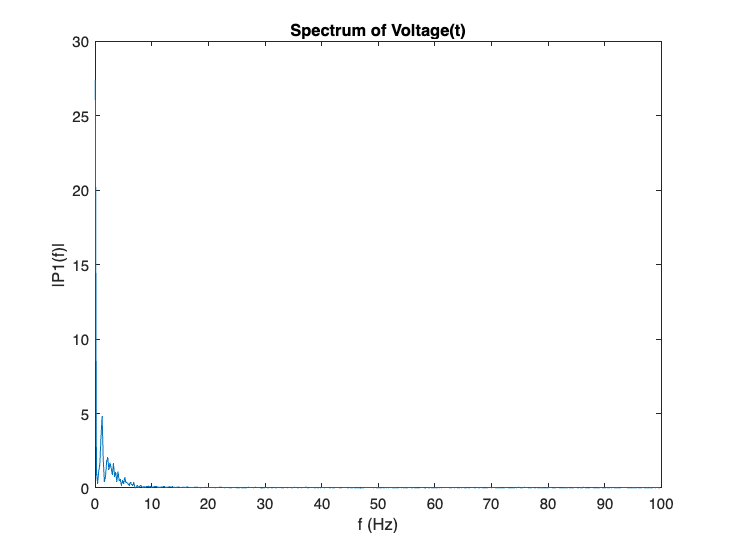

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f, P1);
title('Time-Voltage Spectrum');
xlabel('f (Hz)');
ylabel('Single-Sided Amplitude Spectrum');

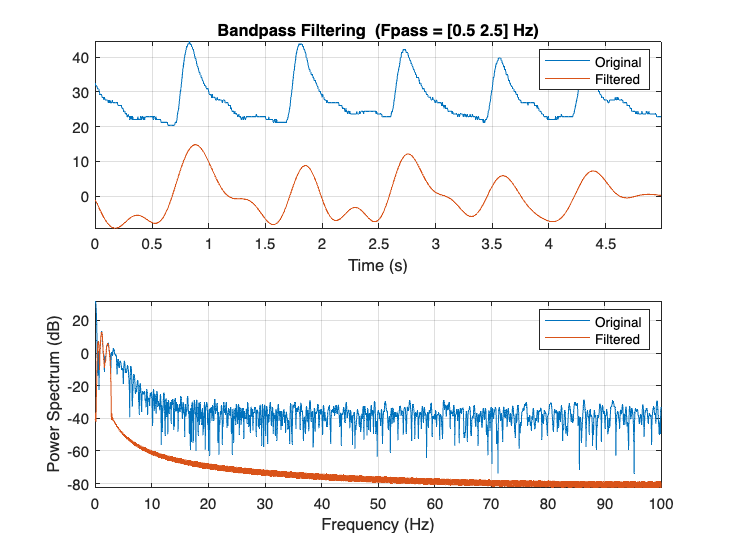

bandpass(signal3,[0.5 2.5],Fs)